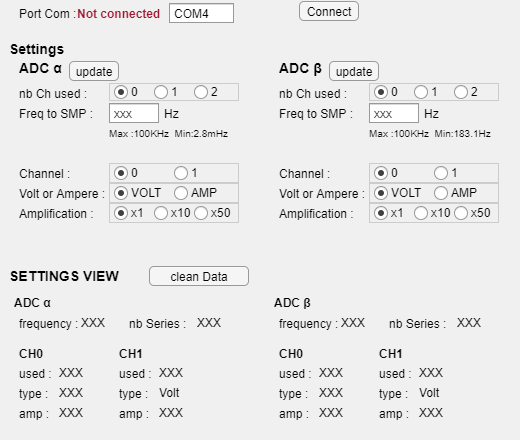

clc
% Create figure window and components
y = 440; x = 520;
x0 = 20;
x1 = 110;
x10 = 260;
x2 = 65;
pos = 20;
fig = uifigure('Position',[200 200 x y], ...
    'Name','SETTINGS DATA-Logger');
fig.Resize=0;

setappdata(fig, 's' ,0) ;
setappdata(fig, 'connected' ,0) ;
% connect
uilabel(fig, 'Position',[x0 y-pos 150 15], 'Text','Port Com :');
ulabConnec = uilabel(fig, 'Position',[x0+58 y-pos 150 15],'Text', 'Not connected',"FontWeight",'bold',"FontColor",'#A2142F');
comText = uitextarea(fig, 'Position',[x1+60 y-pos-2 x2 20],"Value",{'COM4'});

% param
uilabel(fig, 'Position', [10 y-pos*2.8 100 17], 'Text','Settings',"FontWeight",'bold',"FontSize",14);

%ADC1
uilabel(fig, 'Position', [x0 y-pos*4+5 150 17], 'Text','ADC α',"FontWeight",'bold',"FontSize",14);

uilabel(fig, 'Position', [x0 y-pos*5 x1 15], 'Text','nb Ch used :');
bgCHADC1 = uibuttongroup(fig,'Position',[x1 y-pos*5 130 18]);
rb1nbCHADC1 = uiradiobutton(bgCHADC1,'Position',[5 0 60 18],"Text",'0');
rb2nbCHADC1 = uiradiobutton(bgCHADC1,'Position',[45 0 60 18],"Text",'1');
rb3nbCHADC1 = uiradiobutton(bgCHADC1,'Position',[85 0 60 18],"Text",'2');

uilabel(fig, 'Position', [x0 y-pos*6 x1 15], 'Text','Freq to SMP :');
FrecTextADC1 = uitextarea(fig, 'Position',[x1 y-pos*6-2 50 20],"Value",{'xxx'},"WordWrap","off");
uilabel(fig, 'Position', [x1+55 y-pos*6 x1 15], 'Text','Hz');
uilabel(fig, 'Position', [x1 y-pos*7 400 15], 'Text','Max :100KHz  Min:2.8mHz',"FontSize",10);
errorFrecADC1 = uilabel(fig, 'Position', [x1+55+20 y-pos*6 x1 15], 'Text','',"FontColor",'#A2142F',"FontWeight",'bold');

uilabel(fig, 'Position', [x0 y-pos*9 x1 15], 'Text','Channel :');
bgCHADC1 = uibuttongroup(fig,'Position',[x1 y-pos*9-2 130 20]);
rb1CHADC1 = uiradiobutton(bgCHADC1,'Position',[5 0 60 20],"Text",'0');
rb2CHADC1 = uiradiobutton(bgCHADC1,'Position',[65 0 60 20],"Text",'1');

uilabel(fig, 'Position', [x0 y-pos*10 x1 15], 'Text','Volt or Ampere :');
bgVAADC1 = uibuttongroup(fig,'Position',[x1 y-pos*10-2 130 20]);
rb1VAADC1 = uiradiobutton(bgVAADC1,'Position',[5 0 60 20],"Text",'VOLT');
rb2VAADC1 = uiradiobutton(bgVAADC1,'Position',[65 0 60 20],"Text",'AMP');

uilabel(fig, 'Position', [x0 y-pos*11 x1 15], 'Text','Amplification :');
bgAMPADC1 = uibuttongroup(fig,'Position',[x1 y-pos*11-2 130 20]);
rb1AMPADC1 = uiradiobutton(bgAMPADC1,'Position',[5 0 40 20],"Text",'x1');
rb2AMPADC1 = uiradiobutton(bgAMPADC1,'Position',[45 0 40 20],"Text",'x10');
rb3AMPADC1 = uiradiobutton(bgAMPADC1,'Position',[85 0 40 20],"Text",'x50');

%ADC2
uilabel(fig, 'Position', [x0+x10 y-pos*4+5 150 17], 'Text','ADC β',"FontWeight",'bold',"FontSize",14);

uilabel(fig, 'Position', [x0+x10 y-pos*5 x1 15], 'Text','nb Ch used :');
bgCHADC2 = uibuttongroup(fig,'Position',[x1+x10 y-pos*5 130 18]);
rb1nbCHADC2 = uiradiobutton(bgCHADC2,'Position',[5 0 60 18],"Text",'0');
rb2nbCHADC2 = uiradiobutton(bgCHADC2,'Position',[45 0 60 18],"Text",'1');
rb3nbCHADC2 = uiradiobutton(bgCHADC2,'Position',[85 0 60 18],"Text",'2');

uilabel(fig, 'Position', [x0+x10 y-pos*6 x1 15], 'Text','Freq to SMP :');
FrecTextADC2 = uitextarea(fig, 'Position',[x1+x10 y-pos*6-2 50 20],"Value",{'xxx'},"WordWrap","off");
uilabel(fig, 'Position', [x1+55+x10 y-pos*6 x1 15], 'Text','Hz');
uilabel(fig, 'Position', [x1+x10 y-pos*7 400 15], 'Text','Max :100KHz  Min:183.1Hz',"FontSize",10);
errorFrecADC2 = uilabel(fig, 'Position', [x1+55+x10+20 y-pos*6 x1 15], 'Text','',"FontColor",'#A2142F',"FontWeight",'bold');

uilabel(fig, 'Position', [x0+x10 y-pos*9 x1 15], 'Text','Channel :');
bgCHADC2 = uibuttongroup(fig,'Position',[x1+x10 y-pos*9-2 130 20]);
rb1CHADC2 = uiradiobutton(bgCHADC2,'Position',[5 0 60 20],"Text",'0');
rb2CHADC2 = uiradiobutton(bgCHADC2,'Position',[65 0 60 20],"Text",'1');

uilabel(fig, 'Position', [x0+x10 y-pos*10 x1 15], 'Text','Volt or Ampere :');
bgVAADC2 = uibuttongroup(fig,'Position',[x1+x10 y-pos*10-2 130 20]);
rb1VAADC2 = uiradiobutton(bgVAADC2,'Position',[5 0 60 20],"Text",'VOLT');
rb2VAADC2 = uiradiobutton(bgVAADC2,'Position',[65 0 60 20],"Text",'AMP');

uilabel(fig, 'Position', [x0+x10 y-pos*11 x1 15], 'Text','Amplification :');
bgAMPADC2 = uibuttongroup(fig,'Position',[x1+x10 y-pos*11-2 130 20]);
rb1AMPADC2 = uiradiobutton(bgAMPADC2,'Position',[5 0 40 20],"Text",'x1');
rb2AMPADC2 = uiradiobutton(bgAMPADC2,'Position',[45 0 40 20],"Text",'x10');
rb3AMPADC2 = uiradiobutton(bgAMPADC2,'Position',[85 0 40 20],"Text",'x50');

%affichage
uilabel(fig, 'Position', [10 y-pos*14 200 15], 'Text','SETTINGS VIEW',"FontWeight",'bold',"FontSize",14);

%ADC1
uilabel(fig, 'Position', [15 y-pos*15.5 x1 17], 'Text','ADC α',"FontWeight",'bold');
uilabel(fig, 'Position', [x0 y-pos*16.5 x1 15], 'Text','frequency :');
ADC1Frec = uilabel(fig, 'Position', [82 y-pos*16.5-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [x0+110 y-pos*16.5 x1 15], 'Text','nb Series :');
ADC1series = uilabel(fig, 'Position', [198 y-pos*16.5-2 130 20], 'Text','XXX');

uilabel(fig, 'Position', [x0 y-pos*18 x1 15], 'Text','CH0',"FontWeight",'bold');
uilabel(fig, 'Position', [x0 y-pos*19 x1 15], 'Text','used :');
ADC1CH0use = uilabel(fig, 'Position', [60 y-pos*19-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [x0 y-pos*20 x1 15], 'Text','type :');
ADC1CH0VA = uilabel(fig, 'Position', [60 y-pos*20-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [x0 y-pos*21 x1 15], 'Text','amp :');
ADC1CH0Amp = uilabel(fig, 'Position', [60 y-pos*21-2 130 20], 'Text','XXX');

uilabel(fig, 'Position', [x0+100 y-pos*18 x1 15], 'Text','CH1',"FontWeight",'bold');
uilabel(fig, 'Position', [x0+100 y-pos*19 x1 15], 'Text','used :');
ADC1CH1use = uilabel(fig, 'Position', [60+100 y-pos*19-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [x0+100 y-pos*20 x1 15], 'Text','type :');
uilabel(fig, 'Position', [60+100 y-pos*20-2 130 20], 'Text','Volt');
uilabel(fig, 'Position', [x0+100 y-pos*21 x1 15], 'Text','amp :');
ADC1CH1Amp = uilabel(fig, 'Position', [60+100 y-pos*21-2 130 20], 'Text','XXX');

%TM2
uilabel(fig, 'Position', [15+x10 y-pos*15.5 x1 17], 'Text','ADC β',"FontWeight",'bold');
uilabel(fig, 'Position', [x0+x10 y-pos*16.5 x1 15], 'Text','frequency :');
ADC2Frec = uilabel(fig, 'Position', [82+x10 y-pos*16.5-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [x0+110+x10 y-pos*16.5 x1 15], 'Text','nb Series :');
ADC2series = uilabel(fig, 'Position', [198+x10 y-pos*16.5-2 130 20], 'Text','XXX');

uilabel(fig, 'Position', [x0+x10 y-pos*18 x1 15], 'Text','CH0',"FontWeight",'bold');
uilabel(fig, 'Position', [x0+x10 y-pos*19 x1 15], 'Text','used :');
ADC2CH0use = uilabel(fig, 'Position', [60+x10 y-pos*19-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [x0+x10 y-pos*20 x1 15], 'Text','type :');
ADC2CH0VA = uilabel(fig, 'Position', [60+x10 y-pos*20-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [x0+x10 y-pos*21 x1 15], 'Text','amp :');
ADC2CH0Amp = uilabel(fig, 'Position', [60+x10 y-pos*21-2 130 20], 'Text','XXX');

uilabel(fig, 'Position', [x0+100+x10 y-pos*18 x1 15], 'Text','CH1',"FontWeight",'bold');
uilabel(fig, 'Position', [x0+100+x10 y-pos*19 x1 15], 'Text','used :');
ADC2CH1use = uilabel(fig, 'Position', [60+100+x10 y-pos*19-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [x0+100+x10 y-pos*20 x1 15], 'Text','type :');
uilabel(fig, 'Position', [60+100+x10 y-pos*20-2 130 20], 'Text','Volt');
uilabel(fig, 'Position', [x0+100+x10 y-pos*21 x1 15], 'Text','amp :');
ADC2CH1Amp = uilabel(fig, 'Position', [60+100+x10 y-pos*21-2 130 20], 'Text','XXX');

%Button
uibutton(fig,'push', 'Position',[300, y-pos, 60, 20], 'Text', 'Connect', 'ButtonPushedFcn', ...
    @(btn,event) connect(fig,comText.Value,ulabConnec,ADC1Frec,ADC2Frec,ADC1CH0use,ADC1CH1use,ADC2CH0use,ADC2CH1use,ADC1CH0VA,ADC2CH0VA,ADC1CH0Amp,ADC1CH1Amp,ADC2CH0Amp,ADC2CH1Amp,ADC1series,ADC2series,FrecTextADC1,FrecTextADC2,rb1nbCHADC1,rb2nbCHADC1,rb3nbCHADC1,rb1nbCHADC2,rb2nbCHADC2,rb3nbCHADC2));

uibutton(fig,'push', 'Position',[70, y-pos*4, 50, 20], 'Text', 'update', 'ButtonPushedFcn', ...
    @(btn,event) UpdateADC1(fig,rb1nbCHADC1.Value,rb2nbCHADC1.Value,FrecTextADC1.Value,rb1CHADC1.Value,rb1VAADC1.Value,rb1AMPADC1.Value,rb2AMPADC1.Value,ADC1Frec,ADC1CH0use,ADC1CH0VA,ADC1CH0Amp,ADC1CH1use,ADC1CH1Amp,errorFrecADC1));

uibutton(fig,'push', 'Position',[70+x10, y-pos*4, 50, 20], 'Text', 'update', 'ButtonPushedFcn', ...
    @(btn,event) UpdateADC2(fig,rb1nbCHADC2.Value,rb2nbCHADC2.Value,FrecTextADC2.Value,rb1CHADC2.Value,rb1VAADC2.Value,rb1AMPADC2.Value,rb2AMPADC2.Value,ADC2Frec,ADC2CH0use,ADC2CH0VA,ADC2CH0Amp,ADC2CH1use,ADC2CH1Amp,errorFrecADC2));

clean = uibutton(fig,'push', 'Position',[150, y-pos*14-5, 100, 20], 'Text', 'clean Data');
yesDelet = uibutton(fig,'push', 'Position',[260, y-pos*14-5, 40, 20], 'Text', 'YES',"Visible","off");
noDelet = uibutton(fig,'push', 'Position',[300, y-pos*14-5, 40, 20], 'Text', 'NO',"Visible","off");

clean.ButtonPushedFcn= @(btn,event) cleanfonc(yesDelet,noDelet);
yesDelet.ButtonPushedFcn= @(btn,event) deleteData(fig,yesDelet,noDelet,ADC1series,ADC2series);
noDelet.ButtonPushedFcn= @(btn,event) resetClean(yesDelet,noDelet);

function connect (fig,comText,ulabConnec,ADC1Frec,ADC2Frec,ADC1CH0use,ADC1CH1use,ADC2CH0use,ADC2CH1use,ADC1CH0VA,ADC2CH0VA,ADC1CH0Amp,ADC1CH1Amp,ADC2CH0Amp,ADC2CH1Amp,ADC1series,ADC2series,FrecTextADC1,FrecTextADC2,rb1nbCHADC1,rb2nbCHADC1,rb3nbCHADC1,rb1nbCHADC2,rb2nbCHADC2,rb3nbCHADC2)
s = getappdata(fig, 's');
if(s == 0)
    clear('s');
    s = serialport(string(comText),115200);
    setappdata(fig, 's' ,s)
    flush(s,"input");
    flush(s,"output");
    updateParam(fig,ADC1Frec,ADC2Frec,ADC1CH0use,ADC1CH1use,ADC2CH0use,ADC2CH1use,ADC1CH0VA,ADC2CH0VA,ADC1CH0Amp,ADC1CH1Amp,ADC2CH0Amp,ADC2CH1Amp,ADC1series,ADC2series,FrecTextADC1,FrecTextADC2,rb1nbCHADC1,rb2nbCHADC1,rb3nbCHADC1,rb1nbCHADC2,rb2nbCHADC2,rb3nbCHADC2);
    ulabConnec.Text = 'Connected';
    ulabConnec.FontColor='#77AC30';
end
end

function UpdateADC1(fig,rb1nbCHADC1,rb2nbCHADC1,FrecTextADC1,rb1CHADC1,rb1VAADC1,rb1AMPADC1,rb2AMPADC1,ADC1Frec,ADC1CH0use,ADC1CH0VA,ADC1CH0Amp,ADC1CH1use,ADC1CH1Amp,errorFrecADC1)

sendPortComF02 (fig,1,rb1nbCHADC1,rb2nbCHADC1,ADC1CH0use,ADC1CH1use);

frec = str2double(FrecTextADC1);
if(frec > 100e3)
    errorFrecADC1.Text = "/!\ Freq too high";
else
    errorFrecADC1.Text = "";
    period = 48e6/frec;
    period = round(period);
    if(period>=2^32)
        period = period/2;
        if(period>=2^32)
            period = period/2;
            if(period>=2^32)
                if(period>=2^32)
                    errorFrecADC1.Text = "/!\ Freq too low";
                else
                    sendPortComF01(fig,1,period,4,ADC1Frec);
                end
            else
                sendPortComF01(fig,1,period,4,ADC1Frec);
            end
        else
            sendPortComF01(fig,1,period,2,ADC1Frec);
        end
    else
        sendPortComF01(fig,1,period,1,ADC1Frec);
    end
end
sendPortComF03 (fig,1,rb1CHADC1,rb1VAADC1,rb1AMPADC1,rb2AMPADC1,ADC1CH0VA,ADC1CH0Amp,ADC1CH1Amp);
end

function UpdateADC2(fig,rb1nbCHADC2,rb2nbCHADC2,FrecTextADC2,rb1CHADC2,rb1VAADC2,rb1AMPADC2,rb2AMPADC2,ADC2Frec,ADC2CH0use,ADC2CH0VA,ADC2CH0Amp,ADC2CH1use,ADC2CH1Amp,errorFrecADC2)

sendPortComF02 (fig,2,rb1nbCHADC2,rb2nbCHADC2,ADC2CH0use,ADC2CH1use);

frec = str2double(FrecTextADC2);
if(frec > 100e3)
    errorFrecADC2.Text = "ERROR: bigger";
else
    errorFrecADC2.Text = "";
    period = 48e6/frec;
    period = round(period);
    if(period>=2^16)
        period = period/2;
        if(period>=2^16)
            period = period/2;
            if(period>=2^16)
                if(period>=2^16)
                    errorFrecADC2.Text = "ERROR: small";
                else
                    sendPortComF01(fig,2,period,4,ADC2Frec);
                end
            else
                sendPortComF01(fig,2,period,4,ADC2Frec);
            end
        else
            sendPortComF01(fig,2,period,2,ADC2Frec);
        end
    else
        sendPortComF01(fig,2,period,1,ADC2Frec);
    end
end
sendPortComF03 (fig,2,rb1CHADC2,rb1VAADC2,rb1AMPADC2,rb2AMPADC2,ADC2CH0VA,ADC2CH0Amp,ADC2CH1Amp);
end

function sendPortComF01(fig,ADC,PeriodADC,divFrec,ADCFrec)
s = getappdata(fig, 's');
tram = zeros(1,7,'uint8');
tram(1) = 0X01;
if(ADC==1)
    tram(2) = 0X0;
elseif(ADC==2)
    tram(2) = 0X1;
end

X = uint32(PeriodADC);
y= typecast(X,'uint8');

tram(3)=y(1);
tram(4)=y(2);
tram(5)=y(3);
tram(6)=y(4);
if(divFrec==1)
    tram(7) = 0;
elseif (divFrec==2)
    tram(7) = 1;
else
    tram(7) = 2;
end
write(s,tram,"uint8")

RX_text = read(s,2,"uint8");

%update visu
if(RX_text(1)==0x10)
    frecADC = 48e6/((PeriodADC)*divFrec);
    if(frecADC >= 1000)
        ADCFrec.Text=string(frecADC/1000) + " KHz";
    elseif (frecADC < 1)
        ADCFrec.Text=string(frecADC*1000) + " mHz";
    else
        ADCFrec.Text=string(frecADC) + " Hz";
    end
end
end

function sendPortComF02 (fig,ADC,rb1nbCH,rb2nbCH,ADCCH0use,ADCCH1use)
s = getappdata(fig, 's');
tram = zeros(1,3,'uint8');
tram(1) = 0X02;
if(ADC==1)
    tram(2) = 0;
elseif(ADC==2)
    tram(2) = 1;
end

if(rb1nbCH)
    tram(3) = 0;
elseif(rb2nbCH)
    tram(3) = 1;
else
    tram(3) = 2;
end

write(s,tram,"uint8");
RX_text = read(s,2,"uint8");
%update visu
if(RX_text(1)==0x10)
    if(rb1nbCH)
        ADCCH0use.Text = 'no';
        ADCCH1use.Text = 'no';
    elseif(rb2nbCH)
        ADCCH0use.Text = 'yes';
        ADCCH1use.Text = 'no';
    else
        ADCCH0use.Text = 'yes';
        ADCCH1use.Text = 'yes';
    end
end
end

function sendPortComF03 (fig,ADC,rb1CH,rb1VA,rb1AMP,rb2AMP,ADCCH0VA,ADCCH0Amp,ADCCH1Amp)
s = getappdata(fig, 's');
tram = zeros(1,5,'uint8');
tram(1) = 0X03;
if(ADC==1)
    tram(2) = 0;
elseif(ADC==2)
    tram(2) = 1;
end
if(rb1CH)
    tram(3) = 0;
else
    tram(3) = 1;
end

if(rb1VA)
    tram(4) = 0;
else
    tram(4) = 1;
end

if(rb1AMP)
    tram(5) = 0;
elseif(rb2AMP)
    tram(5) = 1;
else
    tram(5) = 2;
end

write(s,tram,"uint8");
RX_text = read(s,2,"uint8");

%update visu
if(RX_text(1)==0x10)
    if(ADC)
        if(rb1CH)
            if(rb1VA)
                ADCCH0VA.Text = 'Volt';
            else
                ADCCH0VA.Text = 'Ampere';
            end
            if(rb1AMP)
                ADCCH0Amp.Text = '*1';
            elseif(rb2AMP)
                ADCCH0Amp.Text = '*10';
            else
                ADCCH0Amp.Text = '*50';
            end
        else
            if(rb1AMP)
                ADCCH1Amp.Text = '*1';
            elseif(rb2AMP)
                ADCCH1Amp.Text = '*10';
            else
                ADCCH1Amp.Text = '*50';
            end
        end
    end
end
end


function updateParam(fig,ADC1Frec,ADC2Frec,ADC1CH0use,ADC1CH1use,ADC2CH0use,ADC2CH1use,ADC1CH0VA,ADC2CH0VA,ADC1CH0Amp,ADC1CH1Amp,ADC2CH0Amp,ADC2CH1Amp,ADC1series,ADC2series,FrecTextADC1,FrecTextADC2,rb1nbCHADC1,rb2nbCHADC1,rb3nbCHADC1,rb1nbCHADC2,rb2nbCHADC2,rb3nbCHADC2)
s = getappdata(fig, 's');
flush(s,"input");
tram = zeros(1,4,'uint8');

%period
tram(1,1) = 0X0B;
tram(1,2) = 0;
write(s,tram,"uint8");
readTX = read(s,7,"uint8");
frecADC1 = 48e6/((readTX(3)+readTX(4)*256+readTX(5)*256^2+readTX(6)*256^3)*2^readTX(7));
if(frecADC1 >= 1000)
    ADC1Frec.Text=string(round(frecADC1/1000,2)) + " KHz";
    FrecTextADC1.Value = string(round(frecADC1,2));
elseif (frecADC1 < 1)
    ADC1Frec.Text=string(round(frecADC1*1000,2)) + " mHz";
    FrecTextADC1.Value = string(round(frecADC1,5));
else
    ADC1Frec.Text=string(round(frecADC1,2)) + " Hz";
    FrecTextADC1.Value = string(round(frecADC1,2));
end


tram(1,1) = 0X0B;
tram(1,2) = 1;
write(s,tram,"uint8");
readTX = read(s,7,"uint8");
frecADC2 = 48e6/((readTX(3)+readTX(4)*256+readTX(5)*256^2+readTX(6)*256^3)*2^readTX(7));
if(frecADC2 >= 1000)
    ADC2Frec.Text=string(frecADC2/1000) + " KHz";
    FrecTextADC2.Value = string(round(frecADC2,2));
elseif (frecADC2 < 1)
    ADC2Frec.Text=string(frecADC2*1000) + " mHz";
    FrecTextADC2.Value = string(round(frecADC2,5));
else
    ADC2Frec.Text=string(frecADC2) + " Hz";
    FrecTextADC2.Value = string(round(frecADC2,2));
end

tram(1,1) = 0X0A;
tram(1,2) = 0;
write(s,tram,"uint8");
readTX = read(s,4,"uint8");
ADC1series.Text = string(readTX(3)*256+readTX(4));

tram(1) = 0X0A;
tram(2) = 1;
write(s,tram,"uint8");
readTX = read(s,4,"uint8");
ADC2series.Text = string(readTX(3)*256+readTX(4));

%use
tram(1,1) = 0X0D;
tram(1,2) = 0;
write(s,tram,"uint8");
readTX = read(s,3,"uint8");
if(readTX(1,3)==0)
    ADC1CH0use.Text = 'no';
    ADC1CH1use.Text = 'no';
    rb1nbCHADC1.Value = true;
elseif(readTX(1,3)==1)
    ADC1CH0use.Text = 'yes';
    ADC1CH1use.Text = 'no';
    rb2nbCHADC1.Value = true;
elseif(readTX(1,3)==2)
    ADC1CH0use.Text = 'yes';
    ADC1CH1use.Text = 'yes';
    rb3nbCHADC1.Value = true;
else
    ADC1CH0use.Text = 'XX';
    ADC1CH1use.Text = 'XX';
    rb1nbCHADC1.Value = true;
end

tram(1) = 0X0D;
tram(2) = 1;
write(s,tram,"uint8");
readTX = read(s,3,"uint8");
if(readTX(3)==0)
    ADC2CH0use.Text = 'no';
    ADC2CH1use.Text = 'no';
    rb1nbCHADC2.Value = true;
elseif(readTX(3)==1)
    ADC2CH0use.Text = 'yes';
    ADC2CH1use.Text = 'no';
    rb2nbCHADC2.Value = true;
elseif(readTX(3)==2)
    ADC2CH0use.Text = 'yes';
    ADC2CH1use.Text = 'yes';
    rb3nbCHADC2.Value = true;
else
    ADC2CH0use.Text = 'XX';
    ADC2CH1use.Text = 'XX';
    rb1nbCHADC2.Value = true;
end

%TM1
tram(1) = 0X0C;
tram(2) = 0;
tram(3) = 0;
write(s,tram,"uint8");
readTX = read(s,5,"uint8");
if(readTX(4)== 0)
    ADC1CH0VA.Text = 'Volt';
elseif(readTX(4)== 1)
    ADC1CH0VA.Text = 'Ampere';
else
    ADC1CH0VA.Text = 'XX';
end

if(readTX(5)==0)
    ADC1CH0Amp.Text = '*1';
elseif(readTX(5)==1)
    ADC1CH0Amp.Text = '*10';
elseif(readTX(5)==2)
    ADC1CH0Amp.Text = '*50';
else
    ADC1CH0Amp.Text = 'XX';
end

tram(1) = 0X0C;
tram(2) = 0;
tram(3) = 1;
write(s,tram,"uint8");
readTX = read(s,5,"uint8");

if(readTX(5)==0)
    ADC1CH1Amp.Text = '*1';
elseif(readTX(5)==1)
    ADC1CH1Amp.Text = '*10';
elseif(readTX(5)==2)
    ADC1CH1Amp.Text = '*50';
else
    ADC1CH1Amp.Text = 'XX';
end

%TM2
tram(1) = 0X0C;
tram(2) = 1;
tram(3) = 0;
write(s,tram,"uint8");
readTX = read(s,5,"uint8");

if(readTX(4)== 0)
    ADC2CH0VA.Text = 'Volt';
elseif(readTX(4)== 1)
    ADC2CH0VA.Text = 'Ampere';
else
    ADC2CH0VA.Text = 'XX';
end
if(readTX(5)==0)
    ADC2CH0Amp.Text = '*1';
elseif(readTX(5)==1)
    ADC2CH0Amp.Text = '*10';
elseif(readTX(5)==2)
    ADC2CH0Amp.Text = '*50';
else
    ADC2CH0Amp.Text = 'XX';
end

tram(1) = 0X0C;
tram(2) = 1;
tram(3) = 1;
write(s,tram,"uint8");
readTX = read(s,5,"uint8");

if(readTX(5)==0)
    ADC2CH1Amp.Text = '*1';
elseif(readTX(5)==1)
    ADC2CH1Amp.Text = '*10';
elseif(readTX(5)==2)
    ADC2CH1Amp.Text = '*50';
else
    ADC2CH1Amp.Text = 'XX';
end
end

function cleanfonc(yesDelet,noDelet)
yesDelet.Visible = 'on';
noDelet.Visible = 'on';
end

function deleteData(fig,yesDelet,noDelet,TM1Series,TM2Series)
s = getappdata(fig, 's');
tram = zeros(1,1,'uint8');
tram(1) = 0x08;
write(s,tram,"uint8");
RX_text = read(s,2,"uint8");
if(RX_text(1)==0x10)
    %dataDelet
    TM1Series.Text='0';
    TM2Series.Text='0';
    resetClean(yesDelet,noDelet);
end
end

function resetClean(yesDelet,noDelet)
yesDelet.Visible = 'off';
noDelet.Visible = 'off';
end